# Creation of Synthetic Hyperspectral TI and TE dataset with MATLAB

In this demo project, we will demostrate how to use endmembers from Cuprite hyperspectral imagery to create Target Inplantation (TI) and Target Embeddedness (TI) synthetic hyperspectral imagery with MATLAB.

## Read Target Spectra (Endmembers)

This demo project use the endmembers taken from Cuprite reflectance hyperspectral data to form synthetic hyperpsectral TI and TE dataset. Downloads the dataset by cloning the tite GitHub repository to the local environment. The dataset is stored in a folder named tite. Then, we can load the variables from the cuprite_minerals_spectra_reflectance.mat file into the MATLAB environment. 

% Download Dataset
if ~exist("./tite/tite_reflectance.mat")
    gitclone("https://github.com/Brunoxue/tite.git");
end

% Load Cuprite endmembers
load('tite/cuprite_minerals_spectra_reflectance.mat');
minerals=double(minerals);
background=double(background);

## 2. Visualizing Endmembers

This demo project use the endmembers taken from Cuprite reflectance hyperspectral data to form synthetic hyperpsectral TI and TE dataset. Display the 5 endmembers spectra which will be to form the TI and TE datasets, along with the background spectrum.

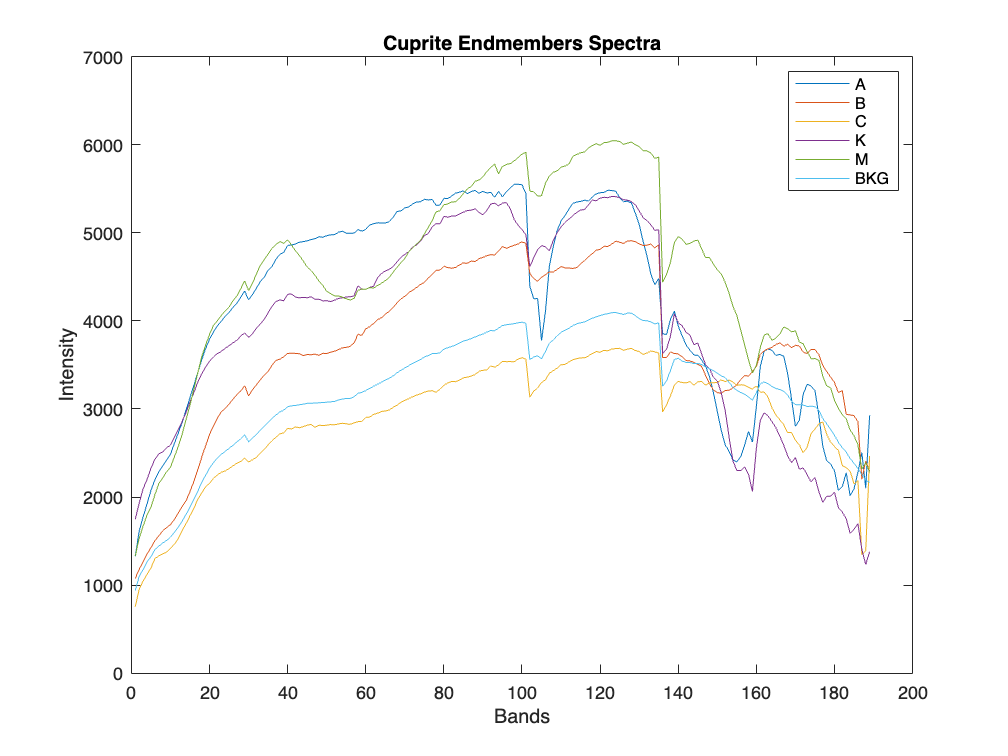

figure;
plot(minerals);
hold on,plot(background);
title("Cuprite Endmembers Spectra");
xlabel("Bands");
ylabel("Intensity")
legend({"A","B","C","K","M","BKG"});

## 3. Simulate the Panel Scene

Now, we can create the TI and TE synthetic hyperspectral image scene.

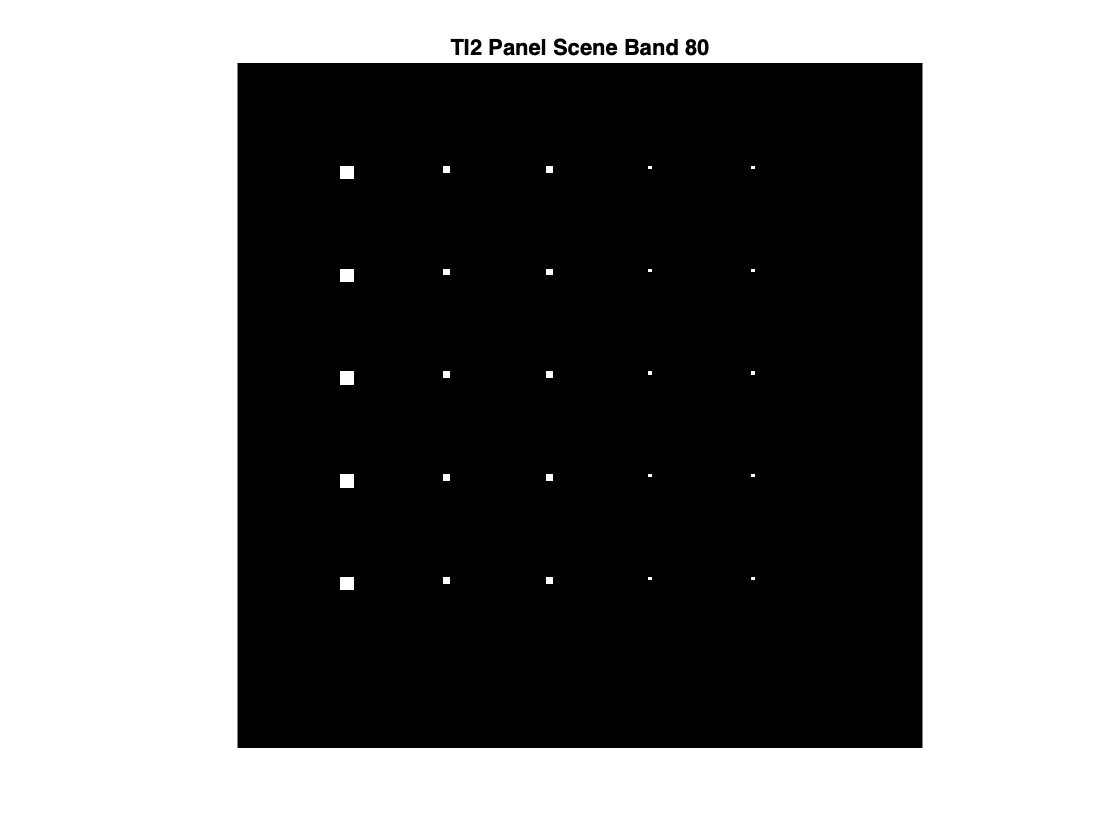

% Create TI and TE
minerals=double(minerals);

% The six_scenarios function can be found in the end of this live script
[TI1,TI2,TI3,TE1,TE2,TE3,GT,GT_abundance_TI,GT_abundance_TE]=six_scenarios(minerals,background);

% Display the results with the 80 band of the TI2 image scene we just created.
figure;
imagesc(TI2(:,:,80)),axis off,axis image;
title("TI2 Panel Scene Band 80");

## 4. Save Created Datasets (in Double)

% Save data to mat file
results.TI1=TI1;
results.TI2=TI2;
results.TI3=TI3;
results.TE1=TE1;
results.TE2=TE2;
results.TE3=TE3;
results.GT_abundance_TI=GT_abundance_TI;
results.GT_abundance_TE=GT_abundance_TE;
results.minerals=minerals;
results.minerals_label=minerals_label;
results.background=background;

save("tite_reflectance.mat", "-struct", "results");

## 5. Save Created Datasets (in I`nteger`)

% Save integer data to mat file
results.TI1=uint16(TI1);
results.TI2=uint16(TI2);
results.TI3=uint16(TI3);
results.TE1=uint16(TE1);
results.TE2=uint16(TE2);
results.TE3=uint16(TE3);
results.GT=uint8(GT);
results.minerals=uint16(minerals);
results.minerals_label=minerals_label;
results.background=background;

save("tite_reflectance.mat", "-struct", "results");

## 6. Check Saved Image

Then, we check if we saved file correctly.

load('tite_reflectance.mat');
hsi=double(TI2);
M=[double(minerals),background];

figure("Units","pixels","Position",[1,1,1000,500]);
tiledlayout(1,2,"Padding","tight");

nexttile,
imagesc(hsi(:,:,100)),axis off,axis image;



nexttile,plot(M);
hold on,plot(background);
title("Cuprite Endmembers Spectra");
xlabel("Bands");
ylabel("Intensity")
legend({"A","B","C","K","M","BKG"});

## Functions for Above Tasks

% Sub-functions
function [TI1,TI2,TI3,TE1,TE2,TE3,GT,GT_abundance_TI,GT_abundance_TE]=six_scenarios(M,BKG)
    % Function six_scenarios for creating TI and TE datasets
    % Composed by Hsiao-Chi Li
    % Modified by Bai Xue
    
    [L,p] = size(M);
    GT = zeros(200);
    GT_abundance = cat(3,zeros(200,200,p),ones(200));

    % simulated white Gaussian noise 
    % snr is 50% of average signal devide by standard deviation of noise
    snr=20;
    sigma=0.5*BKG/snr;
    noise=reshape(repmat(sigma,1,200*200)',200,200,L).*randn(200,200,L);

    % scenario 1: clean target , clean background
    ImageCub=reshape(repmat(BKG,1,200*200)',200,200,size(M,1));
    for k=1:5       % Each row, one endmember will be the main endmember,
        d=M(:,k);   % 1:Alunite, 2:Buddingtonite, 3:Calcite, 4:Kaolinite, 5:Muscovite
        % pure pixels in column 1 (4x4)
        j=1;
        d_abundance = zeros(p+1,1);
        d_abundance(k)=1;
        for m=1:4
            for n=1:4
                ImageCub(30+30*(k-1)+m,30+30*(j-1)+n,:)=d;
                GT(30+30*(k-1)+m,30+30*(j-1)+n,:)=1;
                GT_abundance(30+30*(k-1)+m,30+30*(j-1)+n,:)=d_abundance;
            end
        end
        
        % pure pixels in column 2 (2x2)
        j=2;
        for m=1:2
            for n=1:2
                ImageCub(30+30*(k-1)+m,30+30*(j-1)+n,:)=d;
                GT(30+30*(k-1)+m,30+30*(j-1)+n,:)=1;
                GT_abundance(30+30*(k-1)+m,30+30*(j-1)+n,:)=d_abundance;
            end
        end
        
        % mixed pixel in column 3 (50% of 2 endmembers, 2x2)
        U=M;
        U(:,k)=[];
        U_abundance=[diag(0.5*ones(1,p));zeros(1,p)];
        U_abundance(:,k)=[];
        U_abundance(k,:)=0.5;
        M1=0.5*(repmat(d,1,4)+U);
        j=3;
        for m=1:2
            for n=1:2
                ImageCub(30+30*(k-1)+m,30+30*(j-1)+n,:)=M1(:,2*(m-1)+n);
                GT(30+30*(k-1)+m,30+30*(j-1)+n,:)=1;
                GT_abundance(30+30*(k-1)+m,30+30*(j-1)+n,:)=U_abundance(:,2*(m-1)+n);
            end
        end
        
        % mixed pixel in column 4 (50% of endmember + 50% of Background, 1x1)
        j=4;
        ImageCub(30+30*(k-1)+1,30+30*(j-1)+1,:)=0.5*d+0.5*BKG;
        GT(30+30*(k-1)+1,30+30*(j-1)+1,:)=1;
        GT_abundance(30+30*(k-1)+1,30+30*(j-1)+1,[k,p+1])=0.5;

        % mixed pixel in column 5 (25% of endmember + 75% of Background, 1x1)
        j=5;
        ImageCub(30+30*(k-1)+1,30+30*(j-1)+1,:)=0.25*d+0.75*BKG;
        GT(30+30*(k-1)+1,30+30*(j-1)+1,:)=1;
        GT_abundance(30+30*(k-1)+1,30+30*(j-1)+1,[k,p+1])=[0.25,0.75];

    end
    TI1=ImageCub;
    GT_abundance_TI=GT_abundance;

    % scenario 2: clean target, noisy background
    % remove noise from target area (noise1)
    for i=1:L
        noise1(:,:,i)=noise(:,:,i).*(1-GT);
    end
    TI2=ImageCub+noise1;  % add noise
    
    % scenario 3: noisy target, noisy background
    TI3=ImageCub+noise;   % add noise to whole scene

    % scenario 4: embeded clean target, clean background
    % similar to scenario 1, add target to background instead of insert to it
    ImageCub=reshape(repmat(BKG,1,200*200)',200,200,L);
    for k=1:5
        d=M(:,k);
        j=1;
        for m=1:4
            for n=1:4
                ImageCub(30+30*(k-1)+m,30+30*(j-1)+n,:)=BKG+d;
            end
        end
    
        j=2;
        for m=1:2
            for n=1:2
                ImageCub(30+30*(k-1)+m,30+30*(j-1)+n,:)=BKG+d;
            end
        end
    
        U=M;
        U(:,k)=[];
        M1=0.5*(repmat(d,1,4)+U);
        j=3;
        for m=1:2
            for n=1:2
                ImageCub(30+30*(k-1)+m,30+30*(j-1)+n,:)=BKG+M1(:,2*(m-1)+n);
            end
        end
    
        j=4;
        ImageCub(30+30*(k-1)+1,30+30*(j-1)+1,:)=BKG+0.5*d+0.5*BKG;
    
        j=5;
        ImageCub(30+30*(k-1)+1,30+30*(j-1)+1,:)=BKG+0.25*d+0.75*BKG;
    
    end
    TE1=ImageCub;
    
    % scenario 5: embeded clean target, noisy background
    for i=1:L
        noise1(:,:,i)=noise(:,:,i).*(1-GT);
    end
    TE2=ImageCub+noise1;
    
    % scenario 6: embeded noisy target, noisy background
    TE3=ImageCub+noise;

    BKG_abundance=GT_abundance(:,:,p+1);
    BKG_abundance(BKG_abundance<1)=BKG_abundance(BKG_abundance<1)+1;
    GT_abundance_TE=cat(3,GT_abundance(:,:,1:p),BKG_abundance);

end
